# **2. 🌟 Real data analysis**

**(CC0-BY) seung-goo.kim@ae.mpg.de**

## The study

The dataset for this tutorial is from Vuoskoski et al., (2022) [[https://doi.org/10.1371/journal.pone.0261151](https://doi.org/10.1371/journal.pone.0261151)] and available from Open Science Framework [[https://osf.io/xgj85/](https://osf.io/xgj85/)]. In this study, the authors were interested in relationship between different self-report ratings and acoustic correlates when people listening to emotional music. 

- A total 415 US participants were recruited from Amazon MTurk (mean age = 36 ± 10 years). 

- Seven musical excerpts (115-180 s): ‘Allegri’, ‘Ola- fur’, and ‘Oblivion’, ‘Band of Brothers’, ‘Hoppi- polla’, ‘Vltava’, and ‘Explosions’

- Seven emotional scales: ‘Perceived Sadness’, ‘Perceived Joy’, ‘Feeling Moved or Touched’, ‘Sense of Connection’, ‘Perceived Beauty’, ‘Warmth (in the chest)’, and ‘Chills’.

- For each cell in the 7-by-7 grid, 27-71 ratings were collected (mean = 50).

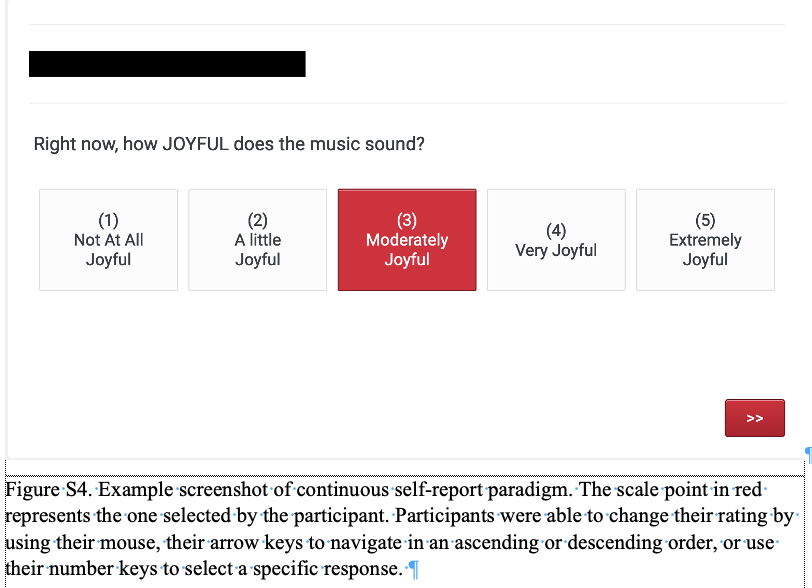

**Fig. 1: A screenshot of the user interface used for the experiment. Taken from Supplementary Material of Vuoskoski et al., (2022).**

## Visual inspection of data

For the sake of demonstration, I have prepared time series dataset of a stimulus feature [audio envelope] and responses [subject-averaged online ratings]. All time series are down-sampled at 1 HZ.

The acceptable data format for LEA requires:

- Time stamps in seconds in the first column

- Values in the second column

- One header row

- Being encoded in plain text, delimited by commas (.csv)

The following is an example of conformed data:

TblX = readtable('./data/env_song1.csv');
figure; plot(TblX(:,1).Variables, TblX(:,2).Variables);
xlabel('Time [s]'); ylabel('Envelope [dB]'); title('Song #1')
TblY = readtable('./data/beauty_song1.csv');
figure; plot(TblY(:,1).Variables, TblY(:,2).Variables)
xlabel('Time [s]'); ylabel('Beauty'); title('Song #1')

The rating time series is not so nice... Nothing happens until 10 seconds, then also flat-lined after 140 seconds. Perhaps high-pass filtering would make this better?

## Dependency structures of data

In addition to the temporal dependency (auto-correlation), isn't there lots of similarity across rating scales?

ScaleNames = ["sad","joy","touched","beauty","connection","warmth","chills"];
R = zeros(7,7,7); % 7x7x7 🙃
for iSong = 1:7
  X = [];
  for iScale = 1:7
    FnTbl = sprintf('./data/%s_song%i.csv', ScaleNames(iScale), iSong);
    assert(isfile(FnTbl))
    Tbl = readtable(FnTbl);
    X = [X, Tbl(:,2).Variables];
  end
  R(:,:,iSong) = corr(X);
end
figure (colormap=flipud(brewermap(256,'spectral')));
for iSong = 1:7
  subplot(3,3,iSong)
  imagesc(R(:,:,iSong),[-1 1]); axis square
  title(sprintf('Song%i',iSong))
  title(colorbaro, 'r')
end
xlabel('Scales'); ylabel('Scales');
set(gca, ytick=1:7,yticklabel=ScaleNames)

### Highpass filtering

PassFreqHz = 0.001;
figure; highpass(TblX(:,2).Variables, PassFreqHz, 1);
figure; highpass(TblY(:,2).Variables, PassFreqHz, 1);

### Modeling with a single response variable

Now, let's run our model and test it. For a demo, let's say our first hypothesis is that the "Touched" scale is encoding (reflecting) the acoustic loudness (audio envelope). For example, a positive change in the envelope would lead to a positive change in the emotional scale.

% setting up the path
addpath('tools/lea')
addpath('tools/sgfunc')
lea_addpath()

% set up a job to run
FnamesX = findfiles('./data/env*');
FnamesY = [findfiles('./data/touched*')];
Job = struct(FnamesX={FnamesX}, FnamesY={FnamesY}, RelToiSec=[15 -15], ...
  DnameMdl='./data/mdl1/', DelaysSmp=(-1:2), HighPassHz=0.001);
[Job] = lea_main(Job);

### Questions:

- What does the result mean?

- Does the result support our hypothesis?

### Modeling with two response variables

Now, let's run our model and test it. Also for a demo, let's say our second hypothesis is that two rating scales ("Touched" and "Beauty") are *positively* encoding (reflecting) the acoustic loudness (audio envelope).

FnamesX = findfiles('./data/env*');
FnamesY = [findfiles('./data/touched*'), findfiles('./data/beauty*')];
Job = struct(FnamesX={FnamesX}, FnamesY={FnamesY}, RelToiSec=[15 -15], ...
  DnameMdl='./data/mdl2/', DelaysSmp=(-1:2), HighPassHz=0.001);
[Job] = lea_main(Job);

### Questions:

- What does this result mean?

- Does the result support our hypothesis?